# **EEE-3102: Numerical Technique Laboratory**

# **Lab-08: Numerical differentiation using MATLAB.**

#### Example-1: Write the following code and see the result.

clear all; close all; clc;
a = 0.1

a = 0.1000

f(1) = 0.5

f = 0.5000

f(2) = (1-a)*f(1)

f =     0.5000    0.4500


f(3) = (1-a)*f(2)

f =     0.5000    0.4500    0.4050


f(4) = (1-a)*f(3)

f =     0.5000    0.4500    0.4050    0.3645


f

f =     0.5000    0.4500    0.4050    0.3645


#### Example-2: Write the following code in a script file.

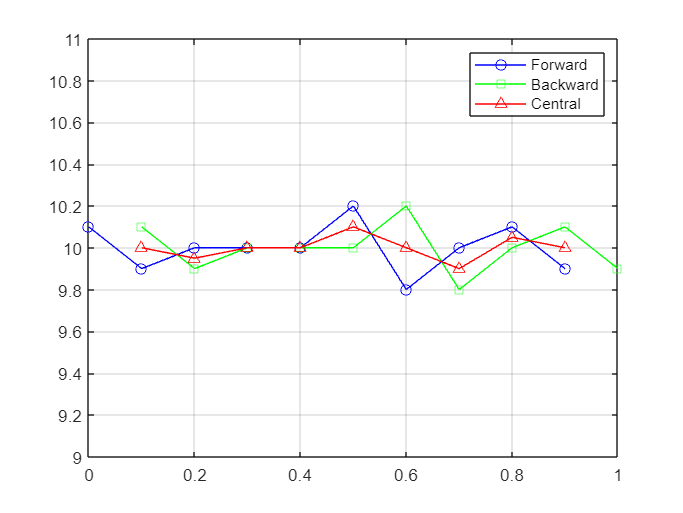

clc;clear all;close all;
t=0:0.1:1;
y=[20 21.01 22 23 24 25 26.02 27 28 29.01 30];
tF=t(1:end-1);
tB=t(2:end);
tC=t(2:end-1);

for i=1:length(t)-1
    dyF(i)=(y(i+1)-y(i))/(t(i+1)-t(i));
end

for i=2:length(t)
    dyB(i-1)=(y(i)-y(i-1))/(t(i)-t(i-1));
end

for i=2:length(t)-1
    dyC(i-1)=(y(i+1)-y(i-1))/(t(i+1)-t(i-1));
end

figure;
plot(tF,dyF,'-bo',tB,dyB,'-gs',tC,dyC,'-r^')
grid on
legend('Forward','Backward','Central')
ylim([9 11])

#### Example-3: Write the following code in a script file.

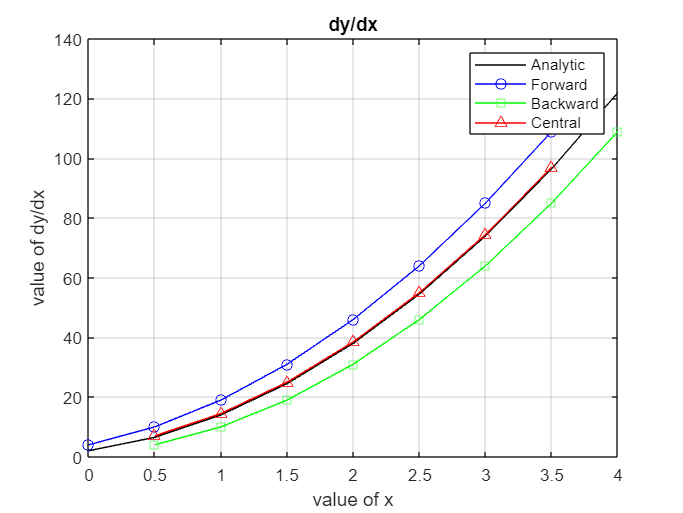

clc;clear all;close all;
x=0:0.5:4;
y=2*x.^3+3*x.^2+2*x+5;
dy =6*x.^2+6*x+2; %Analytical diff of y

xF=x(1:end-1);
xB=x(2:end);
xC=x(2:end-1);

for i=1:length(x)-1
    dyF(i)=(y(i+1)-y(i))/(x(i+1)-x(i)); %Forward Numerical diff of y
end

for i=2:length(x)
    dyB(i-1)=(y(i)-y(i-1))/(x(i)-x(i-1)); %Backward Numerical diff of y
end

for i=2:length(x)-1
    dyC(i-1)=(y(i+1)-y(i-1))/(x(i+1)-x(i-1)); %Central Numerical diff of y
end

figure;
plot(x,dy,'k',xF,dyF,'-bo',xB,dyB,'-gs',xC,dyC,'-r^')
title('dy/dx')
xlabel('value of x')
ylabel('value of dy/dx')
xlim([0 4])
ylim([0 140])
grid on
legend('Analytic','Forward','Backward','Central')

#### Example-4: Try to find out the differentiation of $y=2x^3 +3x^2 +2x+5$ of example-3 using diff function. For this write the following code and observed the graph.

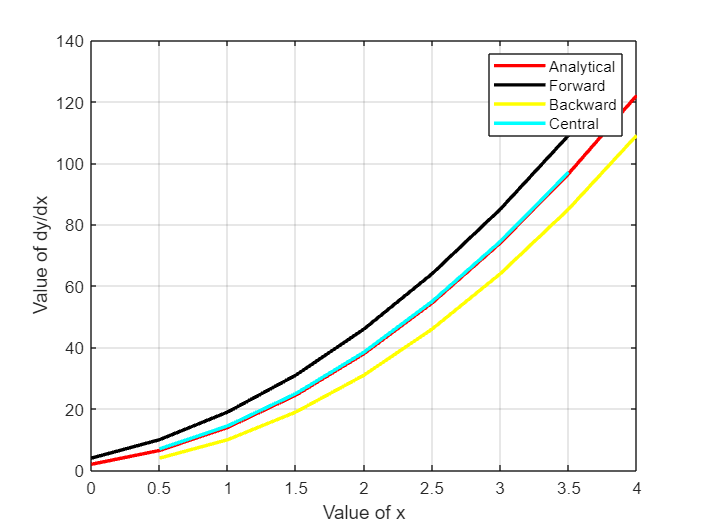

clc; close all; clear all;
x=0:0.5:4;
y = 2*x.^3 + 3*x.^2 + 2*x + 5;
dy = 6*x.^2 + 6*x + 2;

xF = x(1:end-1);
xB = x(2:end);
xC = x(2:end-1);

for i = 1: length(x)-1
    dyF(i) = (y(i+1)-y(i))/ (x(i+1)-x(i));
end

for i = 2: length(x)
    dyB(i-1) = (y(i)-y(i-1))/ (x(i)-x(i-1));
end

for i = 2: length(x)-1
    dyC(i-1) = (y(i+1)-y(i-1))/ (x(i+1)-x(i-1));
end

figure;
plot(x, dy, 'r', xF, dyF, 'k', xB, dyB, 'Y', xC, dyC, 'c', 'linewidth', 2)
xlabel('Value of x');
ylabel('Value of dy/dx');
xlim([0 4])
ylim([0 140])
legend('Analytical', 'Forward', 'Backward', 'Central')
grid on

#### Exercise-1: Let a = 0.75, b=0.09, f(1)=100 and f(x)=(a2+√b)×f(x-1) where x is an integer and x>1.

#### Find f(50) using MATLAB for loop.

clear all; close all; clc; 
a = 0.75; 
b = 0.09; 
f(1) = 100; 
f = double(f); 
for x=2:50 
    f(x) = ((a^2-sqrt(b))*(f(x-1))); 
end 
f=vpa(f); %vpa function is used to find the more digits after decimal point 
f_50=f(50)

$$f\_50 = 0.0000000000000000000000000034461650954365339881862690370194$$

#### Exercise-2: Let t = 0 : 0.1 : 1; and y = [20.1 21 21.9 23 23.9 25 26 27 28.1 29 30.1]. Find dy/dt obtained using forward, backward and central difference and plot the graphs in a single figure.

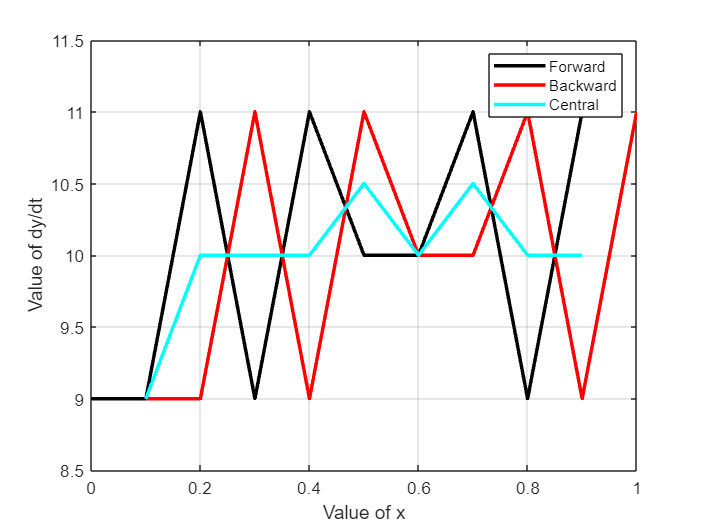

clear all; close all; clc; 
t = 0:0.1:1;
y = [20.1 21 21.9 23 23.9 25 26 27 28.1 29 30.1];
tF = t(1:end-1);
tB = t(2:end);
tC = t(2:end-1);

for i = 1: length(t)-1
    dyF(i) = (y(i+1)-y(i))/ (t(i+1)-t(i));
end

for i = 2: length(t)
    dyB(i-1) = (y(i)-y(i-1))/ (t(i)-t(i-1));
end

for i = 2: length(t)-1
    dyC(i-1) = (y(i+1)-y(i-1))/ (t(i+1)-t(i-1));
end

figure;
plot(tF, dyF, 'k', tB, dyB, 'r', tC, dyC, 'c', 'linewidth', 2)
xlabel('Value of x');
ylabel('Value of dy/dt');

legend('Forward', 'Backward', 'Central')
grid on

#### Exercise-4: Determine the numerical differentiation of the functions in exercise-3 using ‘diff’ MATLAB function and plot the results using ‘ezplot’ function for the specified range of ‘x’ and ‘y’. Also plot the analytical results for the same specified range. You may use subplot MATLAB function to show the results. For y=e^x*sin(3*x); x=[-4:0], y=[-100 100]

clc; close all; clear all; 
syms f(x) 
f(x)=exp(x).*sin(3*x); 
df = diff(f,x) %differentiation using diff function

$$df(x) = 3\,\cos\left(3\,x\right)\,{\mathrm{e}}^{x}+\sin\left(3\,x\right)\,{\mathrm{e}}^{x}$$

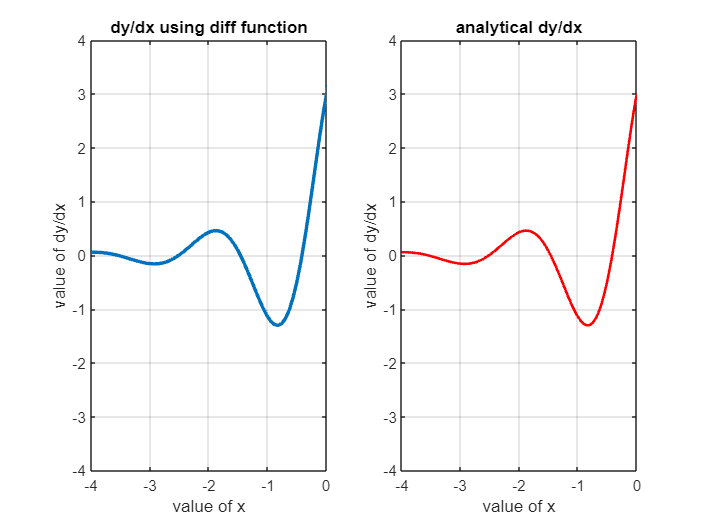

x=-4:0.05:0; 
df_a =exp(x).*sin(3*x)+3*exp(x).*cos(3*x); %analytical differentiation 

figure; 
subplot(1,2,1) 
h=ezplot(df); 
set(h,'LineWidth',2); 
title('dy/dx using diff function') 
xlim([-4 0]) 
ylim([-4 4]) 
xlabel('value of x') 
ylabel('value of dy/dx') 
grid on 

subplot(1,2,2) 
plot(x,df_a,'-r','linewidth',1.5) 
title('analytical dy/dx') 
xlim([-4 0]) 
ylim([-4 4]) 
xlabel('value of x') 
ylabel('value of dy/dx') 
grid on